clc; clear; close all;
disp("MATLAB Exercise: Denavit_Hartenberg to T(Standar DH)")

MATLAB Exercise: Denavit_Hartenberg to T(Standar DH)


n=input( 'i=')

n = 3

DH = zeros(n, 4);
for j=1:n
    DH(j, :) = input(sprintf('input [alpha_{%d}, a_{%d}, d_%d, theta_%d]: ', j-1, j-1, j, j));
end
disp('DH = ');

DH = 


disp(DH);

     0     0     0    10
     0     4     0    20
     0     3     0    30



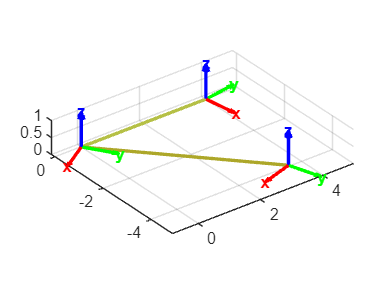

DH_T_{0}_{1}


$$\left(\begin{array}{cccc} \cos\left(10\right) & -\sin\left(10\right) & 0 & 0\\ \sin\left(10\right) & \cos\left(10\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_0_1

$$\left(\begin{array}{cccc} \cos\left(10\right) & -\sin\left(10\right) & 0 & 0\\ \sin\left(10\right) & \cos\left(10\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_{1}_{2}


$$\left(\begin{array}{cccc} \cos\left(20\right) & -\sin\left(20\right) & 0 & 4\\ \sin\left(20\right) & \cos\left(20\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_0_2

$$\left(\begin{array}{cccc} \cos\left(10\right)\,\cos\left(20\right)-\sin\left(10\right)\,\sin\left(20\right) & -\cos\left(10\right)\,\sin\left(20\right)-\cos\left(20\right)\,\sin\left(10\right) & 0 & 4\\ \cos\left(10\right)\,\sin\left(20\right)+\cos\left(20\right)\,\sin\left(10\right) & \cos\left(10\right)\,\cos\left(20\right)-\sin\left(10\right)\,\sin\left(20\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_{2}_{3}


$$\left(\begin{array}{cccc} \cos\left(30\right) & -\sin\left(30\right) & 0 & 3\\ \sin\left(30\right) & \cos\left(30\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

DH_T_0_3

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & 4\,\cos\left(30\right)+3\\ \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & 4\,\sin\left(30\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(30\right)\,\left(\cos\left(10\right)\,\cos\left(20\right)-\sin\left(10\right)\,\sin\left(20\right)\right)-\sin\left(30\right)\,\left(\cos\left(10\right)\,\sin\left(20\right)+\cos\left(20\right)\,\sin\left(10\right)\right)\\ \sigma_{2}=\sin\left(30\right)\,\left(\cos\left(10\right)\,\cos\left(20\right)-\sin\left(10\right)\,\sin\left(20\right)\right)\\ \sigma_{3}=\cos\left(30\right)\,\left(\cos\left(10\right)\,\sin\left(20\right)+\cos\left(20\right)\,\sin\left(10\right)\right) \end{array}$$

syms theta alpha d a
% Rotation matrices
Rz = [cos(theta), -sin(theta), 0;
    sin(theta),  cos(theta), 0;
    0,          0,          1];
Rx = [1, 0,         0;
    0, cos(alpha), -sin(alpha);
    0, sin(alpha), cos(alpha)];
Dz=[0;0;d];
Dx=[a;0;0];
O=[0;0;0];
O3=eye(3);
T_Rz=[Rz,O;0,0,0,1];
T_Rx=[Rx,O;0,0,0,1];
T_Dz=[O3,Dz;0,0,0,1];
T_Dx=[O3,Dx;0,0,0,1];
DH_T_nd1_n=T_Rx*T_Dx*T_Rz*T_Dz;%{i}相对于{i-1}映射的齐次变换矩阵

DH_I=eye(4);
figure;
for j=1:n
    DH_cal=subs(DH_T_nd1_n,[theta,alpha,a,d],[DH(j,4),DH(j,1),DH(j,2),DH(j,3)]);
    fprintf('DH_T_{%d}_{%d}\n',j-1,j);
    disp(DH_cal);
    fprintf('DH_T_0_%d',j);
    DH_I=DH_cal*DH_I;
    disp(DH_I);
    R=DH_I(1:3,1:3);%提取出旋转矩阵，表示姿态
    P=DH_I(1:3, 4);%提取位置矢量
    plot3([0,P(1)],[0,P(2)],[0,P(3)],'Color', rand(1,3),'LineWidth', 2)
    drawFrame(P,R);
end